# Lab random signal processing

## S1: Autocorrelation estimators

Objectives of the first lab session: discovery of the topic, reliable estimation of the autocorrelation, criteria to determine the voiced or unvoiced nature of a sound

### 1) sample data

Here we created the random proceses we know the autocorrelation function

First we need some constants, to all the programs to work

clearvars
close all
clc
%Number of samples of the noise
N = 500;

%Maximun number of p shifts
P_max = N-1;

%sampling frequency
Fs = 8000;

%Voiced file names
unvoiced_names = [...
    "./data/nonvoise_ch" "./data/nonvoise_hw" ...
    "./data/nonvoise_kss" "./data/nonvoise_th" ...
    ];

%voiced file names
voiced_names = [...
    "./data/voise_nng" "./data/voise_oo" ...
    "./data/voise_ooo" ...
    ];

White Noise (normaly distributed):

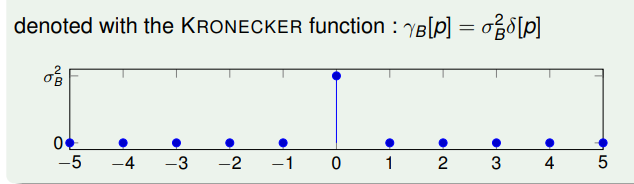

white_noise_variance = 1;
white_noise_deviation = sqrt(white_noise_variance);
white_noise_mean = 0;

white_noise = white_noise_mean + white_noise_deviation .*randn(1,N);

white_noise_autocorr = zeros(1,N);
white_noise_autocorr(1) = white_noise_variance;

AR(1) Function:

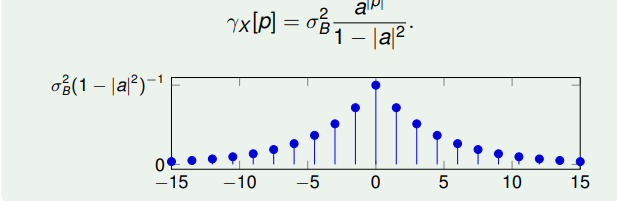

AR1_variance = 1;
AR1_deviation = sqrt(AR1_variance);
AR1_coefficient = 0.9;

AR1 = filter(1, [1 -AR1_coefficient],AR1_deviation.*randn(1,N));

AR1_autocorr = AR1_variance .* AR1_coefficient.^abs(0:P_max);
AR1_autocorr = AR1_autocorr./ (1-abs(AR1_coefficient).^2);

Sine wave with random phase (uniformaly distributed):

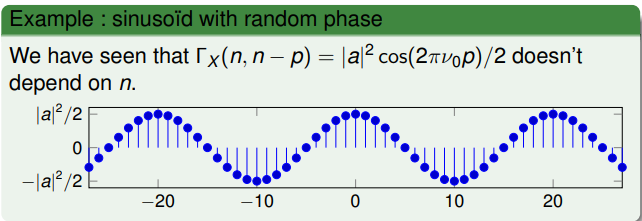

sine_amplitude = 2;
sine_reduced_frequency = 0.20; % range [0,0.5)
sine_phase_shifts = 2.*pi.*rand(1,N);
sine_angules = 2.*pi.*sine_reduced_frequency.*(1:N);

sine = sine_amplitude.*sin(sine_angules + sine_phase_shifts);

sine_autocorr = (abs(sine_amplitude).^2) ./ 2;
sine_autocorr = sine_autocorr .* cos(2.*pi.*sine_reduced_frequency.*(0:P_max));

Now we graph them

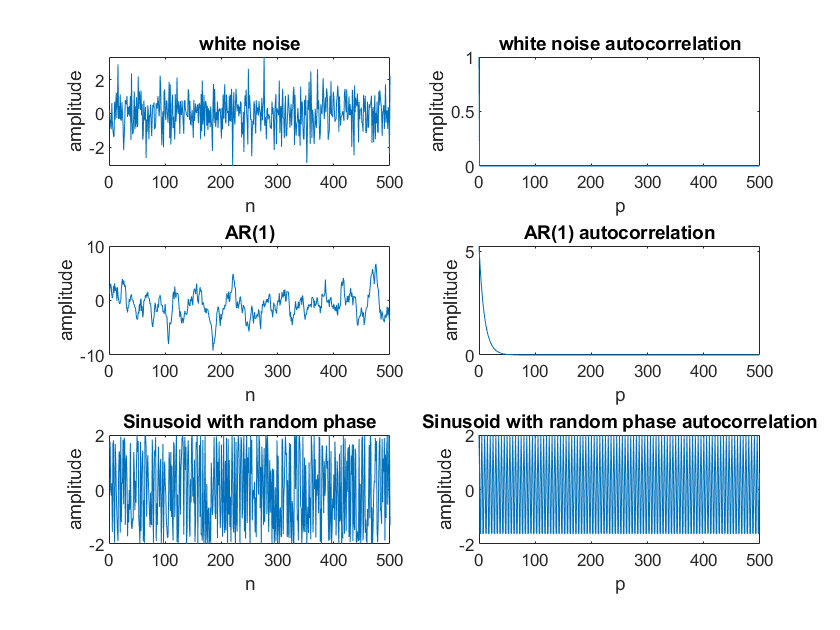

%plot
figure(1)
x_axis_n = 1:N;
x_axis_p = 0:P_max;

subplot(3,2,1)
plot(x_axis_n,white_noise)
title("white noise")
xlabel("n"), ylabel("amplitude")

subplot(3,2,2)
plot(x_axis_p,white_noise_autocorr)
title("white noise autocorrelation")
xlabel("p"), ylabel("amplitude")

subplot(3,2,3)
plot(x_axis_n,AR1)
title("AR(1)")
xlabel("n"), ylabel("amplitude")

subplot(3,2,4)
plot(x_axis_p,AR1_autocorr)
title("AR(1) autocorrelation")
xlabel("p"), ylabel("amplitude")

subplot(3,2,5)
plot(x_axis_n,sine)
title("Sinusoid with random phase")
xlabel("n"), ylabel("amplitude")

subplot(3,2,6)
plot(x_axis_p,sine_autocorr)
title("Sinusoid with random phase autocorrelation")
xlabel("p"), ylabel("amplitude")

### 2) Biased autocorrelation estimator

we created a funcion (inside its own script) to implement the Biased autocorrelation estimator$^{1}$. 

Inputs:

- `X`: vector of signal samples

-  `pmax`: maximal amount of shift to be considered (optional, defaults to the length of X minus 1)

Outputs:

- `Cx`: vector of cross correlation samples for shifts varying from 0 to pmax

- `p`: vector of corresponding shifts

$^{1}$[We decided to not change the name of the function, but we think that the name is not the correct one. The title of the section is biased autocorrelation estimator, but the function is caled biased cross correlation, and only accepts one vector of signal samples].


$$\widehat{\gamma_{\mathrm{Xb}} } \left(p,\omega \right)\frac{1}{N}\sum_{k=p}^{N-1} X\left(k,\omega \right){X\left(k,\omega \right)}^*$$


#### testing

Now we test this stimator against the real autocorrelation of the functions:

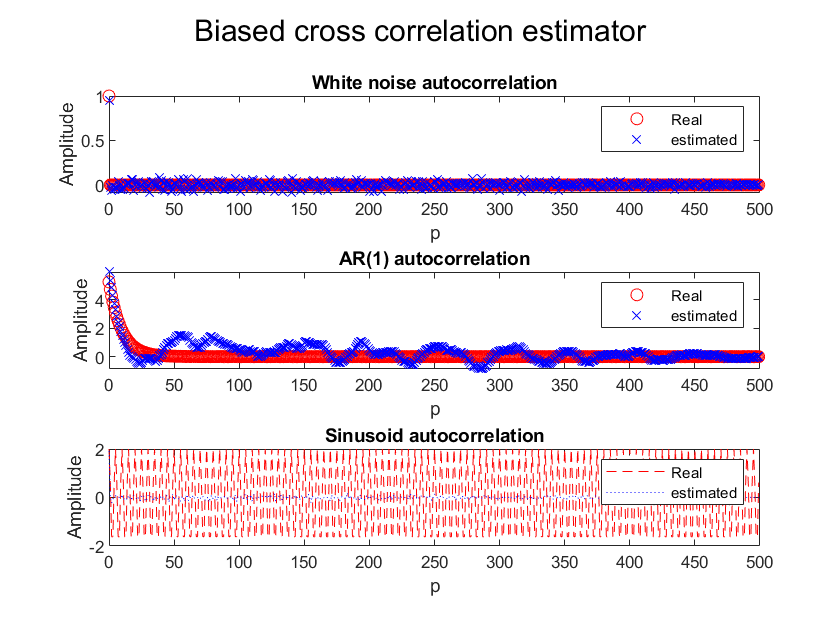

%plot
figure(2)
sgtitle("Biased cross correlation estimator")
est_white_noise = BiasedCrossCorr(white_noise);
est_AR1 = BiasedCrossCorr(AR1);
est_sine = BiasedCrossCorr(sine);

subplot(3,1,1)
plot(x_axis_p,white_noise_autocorr,"ro")
hold on
plot(x_axis_p,est_white_noise,"bx")
title("White noise autocorrelation")
xlabel("p")
ylabel("Amplitude")
legend("Real","estimated")

subplot(3,1,2)
plot(x_axis_p,AR1_autocorr,"ro")
hold on
plot(x_axis_p,est_AR1,"bx")
title("AR(1) autocorrelation")
xlabel("p")
ylabel("Amplitude")
legend("Real","estimated")

subplot(3,1,3)
plot(x_axis_p,sine_autocorr,"r--")
hold on
plot(x_axis_p,est_sine,"b:")
title("Sinusoid autocorrelation")
xlabel("p")
ylabel("Amplitude")
legend("Real","estimated")

Then, were are the questions and the answers:

- For random processes for which you know the theoretical autocorrelation function, does the biased estimator converge when the number of samples grows? 

Yes:

N=50

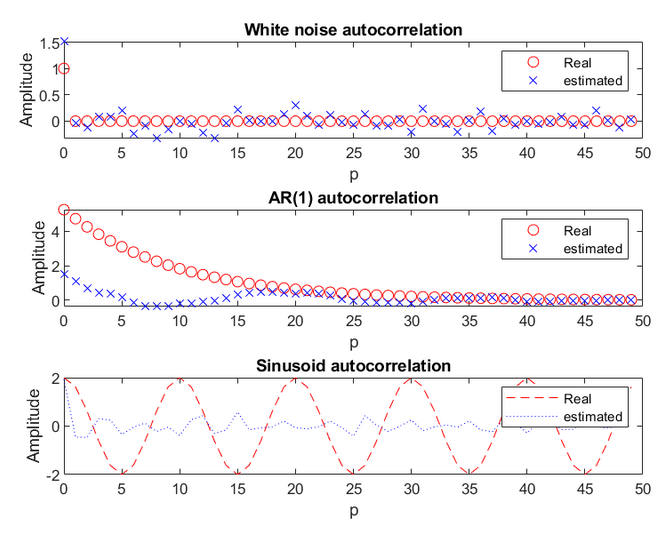

N=500 (First 50 values)

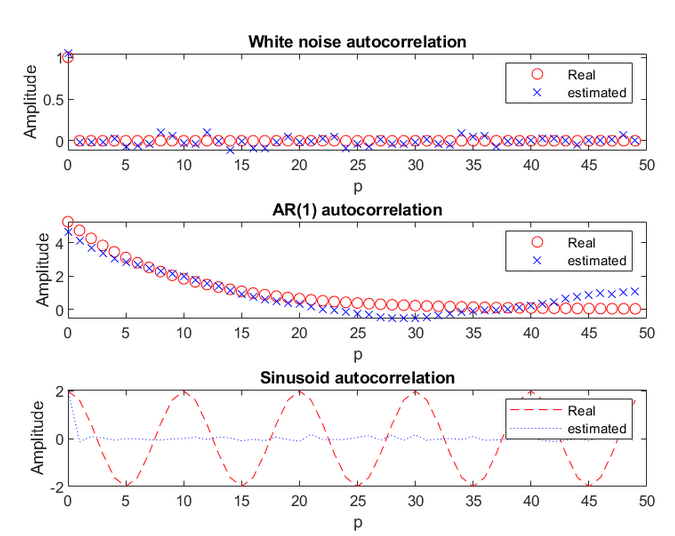

- Can you observe the effect of the bias through certain examples? 

There seems to be some problems with the sinusoid, and the values of the AR(1) seems to be a bit lower in the middle of the graph

- Does the estimated autocorrelation for shift p = 0 match the output of the var function? 

disp(est_white_noise(1) + " | " + var(white_noise))

0.95027 | 0.95185


disp(est_AR1(1) + " | " + var(AR1))

5.9592 | 5.3524


disp(est_sine(1) + " | " + var(sine))

1.9119 | 1.9154


For our value of N (N=500 at the moment of answering), it seems that is almost identical.

- Is the biased estimator more suitable for voiced or unvoiced sounds? 

we have this text from the guide:

-  **voiced**, corresponding to vocal vibrations, modeled by a periodic pulse with random phase (this for example the case for vowels, and for the sounds ‘b’, ‘d’ and ‘z’), 

- **unvoiced**, corresponding to a turbulent flow of exhaled air, modeled by a white noise (this is for example the case for the sounds ‘p’, ‘t’, ‘s’ and ‘ch’)

in this case, it is better for unvoiced sounds, as it does not work well with sinusoids and works really well with white noises.

- What happens if the signal contains a continuous component, representing a random process which is not zero-mean? How to correctly estimate its autocorrelation?

white_noise_variance_unc = 1;
white_noise_deviation_unc = sqrt(white_noise_variance_unc);
white_noise_mean_unc = 3;

white_noise_unc = white_noise_mean_unc + white_noise_deviation_unc .*randn(1,N);

%plot
figure(3)
plot(x_axis_p,BiasedCrossCorr(white_noise_unc))
title("uncentered white noise biased autocorrelation")
xlabel("p")
ylabel("Amplitude")

We can see that the stimation became something really different. To correctly stimate the autocorrelation, we have to estimate the mean effect too. In this case, substracting the mean to the value before the autocorrelation works (code below)

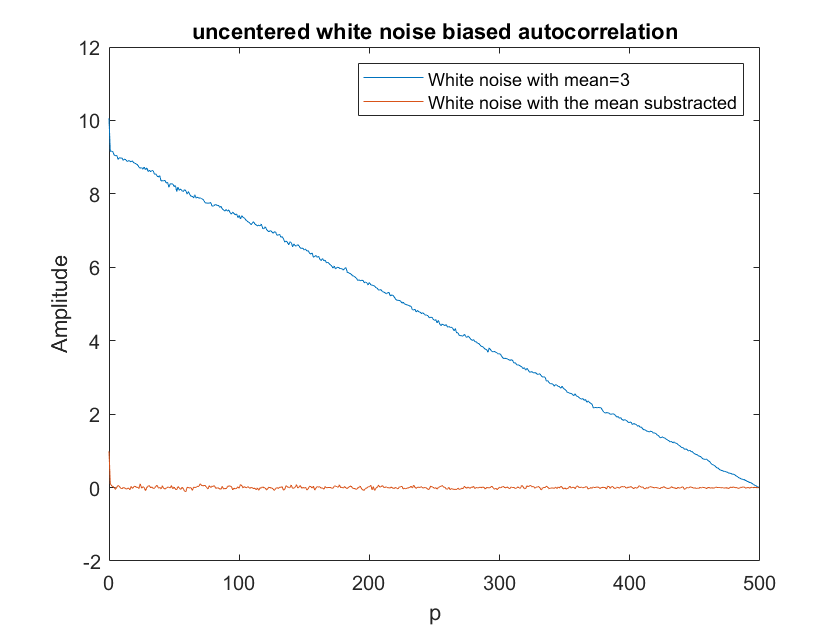

hold on
white_noise_variance_unc = 1;
white_noise_deviation_unc = sqrt(white_noise_variance_unc);
white_noise_mean_unc = 3;

white_noise_unc = white_noise_mean_unc + white_noise_deviation_unc .*randn(1,N);

figure(3)
plot(x_axis_p,BiasedCrossCorr(white_noise_unc-white_noise_mean_unc))
legend("White noise with mean=3", "White noise with the mean substracted")

### 3) Unbiased autocorrelation estimator

we created a funcion (inside its own script) to implement the unbiased autocorrelation estimator$^{2}$. 

Inputs:

- `X`: vector of signal samples

-  `pmax`: maximal amount of shift to be considered (optional, defaults to the length of X minus 1)

Outputs:

- `Cx`: vector of cross correlation samples for shifts varying from 0 to pmax

- `p`: vector of corresponding shifts

$^{2}$[As the previous one, we decided to not change the name of the function, but we think that the name is not the correct one. The title of the section is unbiased autocorrelation estimator, but the function is caled unbiased cross correlation, and only accepts one vector of signal samples].


$$\widehat{\gamma_{\mathrm{Xnb}} } \left(p,\omega \right)\frac{1}{N-p}\sum_{k=p}^{N-1} X\left(k,\omega \right){X\left(k,\omega \right)}^*$$


Test:

#### testing

Now we test this stimator against the real autocorrelation of the functions:

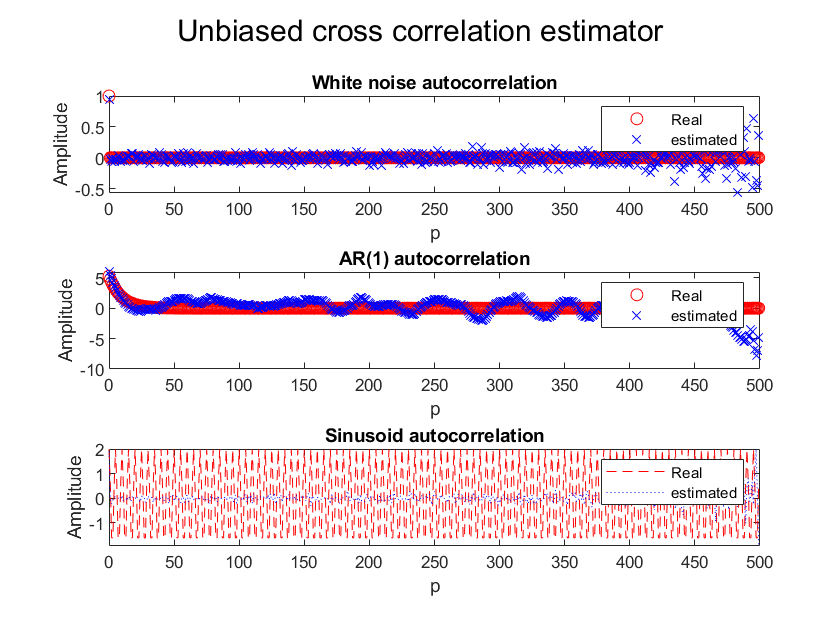

figure(4)
sgtitle("Unbiased cross correlation estimator")
est2_white_noise = UnbiasedCrossCorr(white_noise);
est2_AR1 = UnbiasedCrossCorr(AR1);
est2_sine = UnbiasedCrossCorr(sine);

subplot(3,1,1)
plot(x_axis_p,white_noise_autocorr,"ro")
hold on
plot(x_axis_p,est2_white_noise,"bx")
title("White noise autocorrelation")
xlabel("p")
ylabel("Amplitude")
legend("Real","estimated")

subplot(3,1,2)
plot(x_axis_p,AR1_autocorr,"ro")
hold on
plot(x_axis_p,est2_AR1,"bx")
title("AR(1) autocorrelation")
xlabel("p")
ylabel("Amplitude")
legend("Real","estimated")

subplot(3,1,3)
plot(x_axis_p,sine_autocorr,"r--")
hold on
plot(x_axis_p,est2_sine,"b:")
title("Sinusoid autocorrelation")
xlabel("p")
ylabel("Amplitude")
legend("Real","estimated")

Then, were are the questions and the answers:

- For random processes for which the theoretical autocorrelation is known, does the unbiased estimator converge when the number of samples grows? Do you actually observe a zero bias? 

N=50

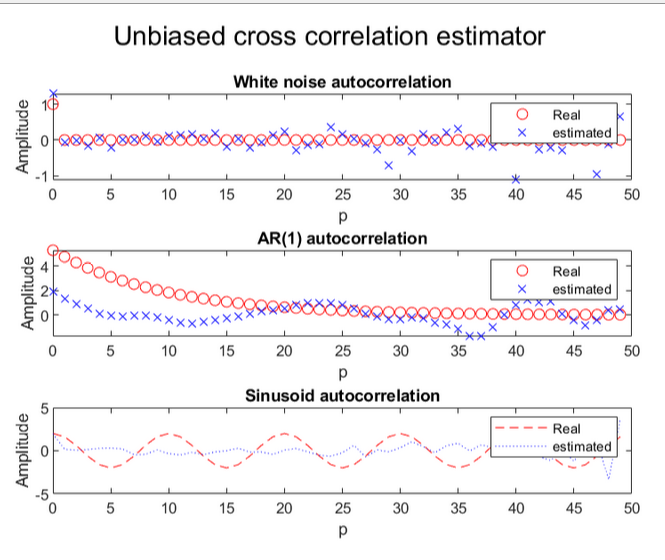

N=500 (first 50)

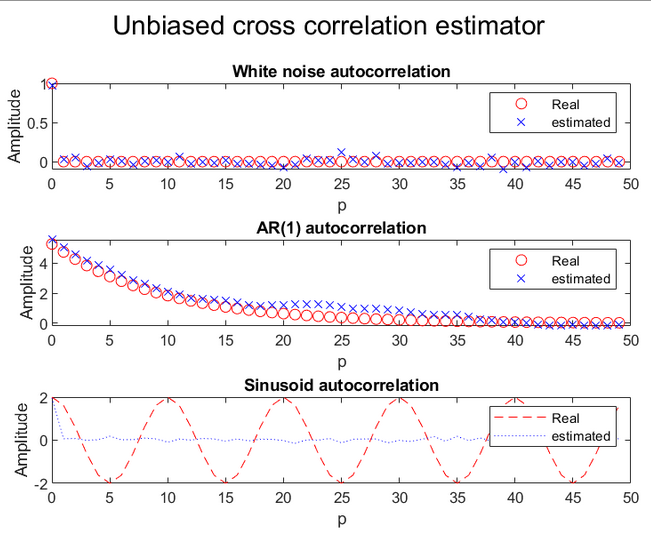

N=500

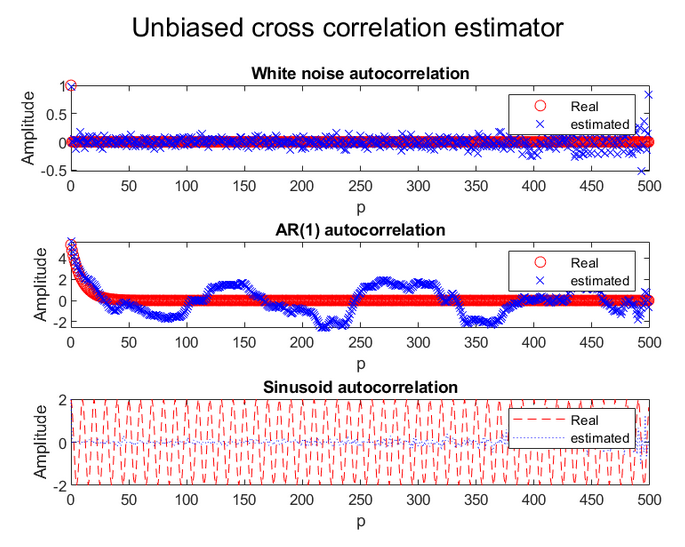

It seems to converge, but there is a problem of convergence at the last values of the shift. I do not observe a 0 bias, but it seems to have done something.

- Can you observe the effect of the variance of the estimator through certain examples? 

disp(est2_white_noise(1) + " | " + est_white_noise(1) + " | " + var(white_noise))

0.95027 | 0.95027 | 0.95185


disp(est2_AR1(1) + " | " + est_AR1(1) + " | " + var(AR1))

5.9592 | 5.9592 | 5.3524


disp(est2_sine(1) + " | " + est_sine(1) + " | " + var(sine))

1.9119 | 1.9119 | 1.9154


For our value of N (N=500 at the moment of answering), it seems that they are the same as in the unbiased ones. If we reduce N to 50, they are the same again, but they differ a considerable amount for the AR(1). If we reduce N to 10, they are the same again, but the error became bigger.

- Is the unbiased estimator more suitable for voiced or unvoiced sounds?

We would said voiced sounds, as we could see if we zoom that the sinusodial now have some meaningful pattern instead of something almost flat.